S = 20; % size of symbols in pixels
% normalize vector to go from zero to 1
normV = (data.t-min(data.t))./(max(data.t)-min(data.t))

normV =          0
    0.0085
    0.0369
    0.0434
    0.0725
    0.0794
    0.1210
    0.1844
    0.1988
    0.2167


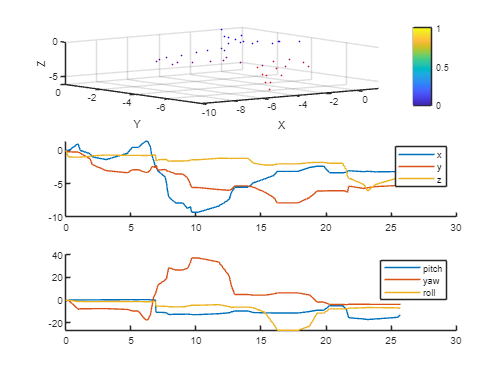

% blue to red. 
C = [normV zeros(size(normV)) 1-normV];

% jet colors
CC = jet(numel(normV));


figure
subplot(3,1,1)
scatter3(data.x, data.z, data.y, S, C,'Marker', '.')
colorbar('vert')
xlabel('X')
ylabel('Y')
zlabel('Z')
subplot(3,1,2)
hold on
plot(data.t,data.x)
plot(data.t,data.z)
plot(data.t,data.y)
legend(["x" "y" "z"])
subplot(3,1,3)
hold on
plot(data.t,data.pitch)
plot(data.t,data.yaw)
plot(data.t,data.roll)
legend(["pitch" "yaw" "roll"])